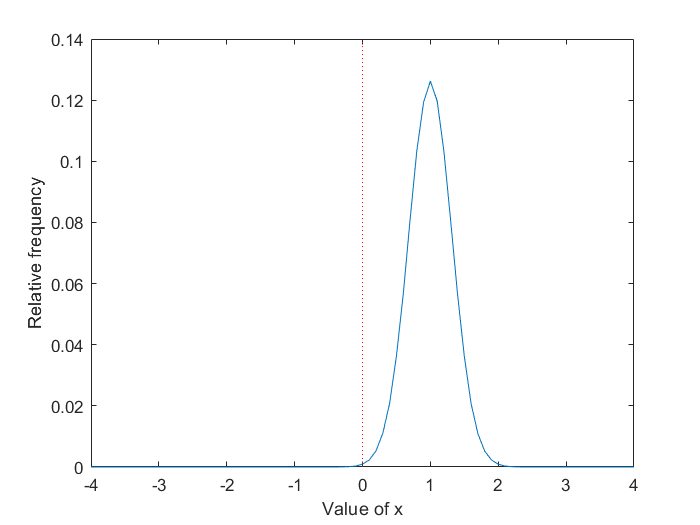

%% ========== Matlab code sample for Practicum 2 ===========
% Simulation: Error Rates in Digital Communications
% Robert Bara
%
clear 
N = 1e6;                      		    % number of bits transmitted

%Make 5 for Parts 1 and 2, make 10 for Parts 3 and 4
SNR_dB = 10;                     		% signal-to-noise ratio in dB  
sigma = 10^(-SNR_dB/20);                % noise standard deviation
mu_w=0;
mu_s=1;


BER_P=normcdf(0,mu_s,sigma);          % Analytically Calculating P(x<0) based on sigma and Mu
 
signal = ones(N,1);     		        % bit stream with only 1's
noise = randn(N,1)* sigma;  	        % additive Gaussian noise
received = (signal*2-1) + noise;		% received noisy signal

x_range = [-4:0.1:4];

% Plotting Relative Frequency
hist_x = hist(received, [-4:0.1:4]);
plot(x_range, hist_x/N);
xlabel('Value of x')
ylabel('Relative frequency')
vline([0])


%Experimentally finding sigma
sigma_EX=std(received);

%Experimentally finding the Experimental Signal Value E[X]
E_X=mean((signal*2-1)+mu_w);

%Experimental BER Analysis
detect = (received > 0);        		% detected result
N_err = sum(abs(detect-signal)); 	% # of erroneously detected bits
BER=N_err/N;                            % Ratio of Error to total bits
fprintf("STD(sigma) = %d, E[x] = %d\n", sigma_EX, E_X)

STD(sigma) = 3.159102e-01, E[x] = 1


fprintf('N = %d bits transmitted; N_err = %d error bits received\n BER = %d \n', N, N_err,BER)

N = 1000000 bits transmitted; N_err = 805 error bits received
 BER = 8.050000e-04 
